# ANOVA Example

Andrew Brown

GEEN 3853

10/23/2020

## INTRODUCTION

Selenium (Se) is a trace metal that is an essential component of a balanced diet, and the amount of selenium in meats can vary based on region based on the selenium levels in that regions soil and plants [1]. A 2002 study looked at the Se content of different meats in a low-Se region of the US, namely Ohio [2]. While certain regions can have low Se content, this often does not result in Se deficiencies in developed countries because of how much food is distributed across regional boundaries [1]. 

The abstract of the 2002 study is included below. Utilize a simplified version of this study’s dataset and verify this study’s results. I.e., conduct a comparison of the Se content of non- region-raised beef, region-raised beef, squirrel, and venison (deer) using the appropriate statistical procedures. Submit complete 7-step procedures for each phase of the hypothesis testing. Also, include a final section that discusses the implications/conclusions of your analysis—what does your analysis tell you with regard to your overall research question? Be sure to include an effect size, post-hoc-analysis table, group subsets, and point and interval estimates, if applicable.

Abstract:

The selenium (Se) content (AOAC fluorometric method) of: 1) raw and cooked venison, squirrel, and beef from a low selenium region of the United States and 2) nonregion‐ raised beef was assessed and compared by region, species, and gender. For both raw and cooked meats, the Se content of venison was not different from region‐raised beef (p > .05), and their contents were generally less than squirrel, which was less than nonregion‐raised beef (p < .05). Gender and age did not influence Se content of the meats. Field‐dressed weight did not affect Se content of deer, and antler size did not impact Se content of meat from male deer. [2]

## PREP WORKSPACE

clear all
close all
clc

## LOAD THE DATA

We first load the dataset titled "NoDifference"

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["type", "selenium"];
opts.VariableTypes = ["categorical", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "type", "EmptyFieldRule", "auto");

% Import the data
raw = readtable("C:\Users\andre\OneDrive\Documents\MATLAB\GEEN 3583\Se_meats_OH.csv", opts)

raw = 144×2 table
    type    selenium
    ____    ________

    NRB       44.33 
    NRB       76.86 
    NRB        4.45 
    NRB       55.01 
    NRB       58.21 
    NRB       74.72 
    NRB       11.84 
    NRB      139.09 
    NRB       69.01 
    NRB       94.61 
    NRB       48.35 
    NRB       37.65 
    NRB       66.36 
    NRB       72.48 
    NRB       87.09 
    NRB       26.34 


## CLEAN AND SUBSET THE DATA

View the dataset and perform necessary cleanup.

%View the first five rows of all columns
raw(:,:)

ans = 144×2 table
    type    selenium
    ____    ________

    NRB       44.33 
    NRB       76.86 
    NRB        4.45 
    NRB       55.01 
    NRB       58.21 
    NRB       74.72 
    NRB       11.84 
    NRB      139.09 
    NRB       69.01 
    NRB       94.61 
    NRB       48.35 
    NRB       37.65 
    NRB       66.36 
    NRB       72.48 
    NRB       87.09 
    NRB       26.34 


%We want all rows and columns.
NRB = table2array(raw(1:19,2));    % Non-region Raised beef
RRB = table2array(raw(20:72,2));   % Region Raised beef
SQU = table2array(raw(73:102,2));  % Squirrel
VEN = table2array(raw(103:144,2)); % Venison
data = [NRB;RRB;SQU;VEN];          % All data
zdata = [zeros(length(NRB), 1); ones(length(RRB), 1); 2*ones(length(SQU), 1); 3*ones(length(VEN), 1)];
meatType = {'NRB','RRB','SQU','VEN'};
extremes_NRB = [min(NRB), max(NRB)];
extremes_RRB = [min(RRB), max(RRB)];
extremes_SQU = [min(SQU), max(SQU)];
extremes_VEN = [min(VEN), max(VEN)];

# DESCRIPTIVE STATISTICS

## DESCRIPTIVE STATISTICS - VISUAL

### Histograms

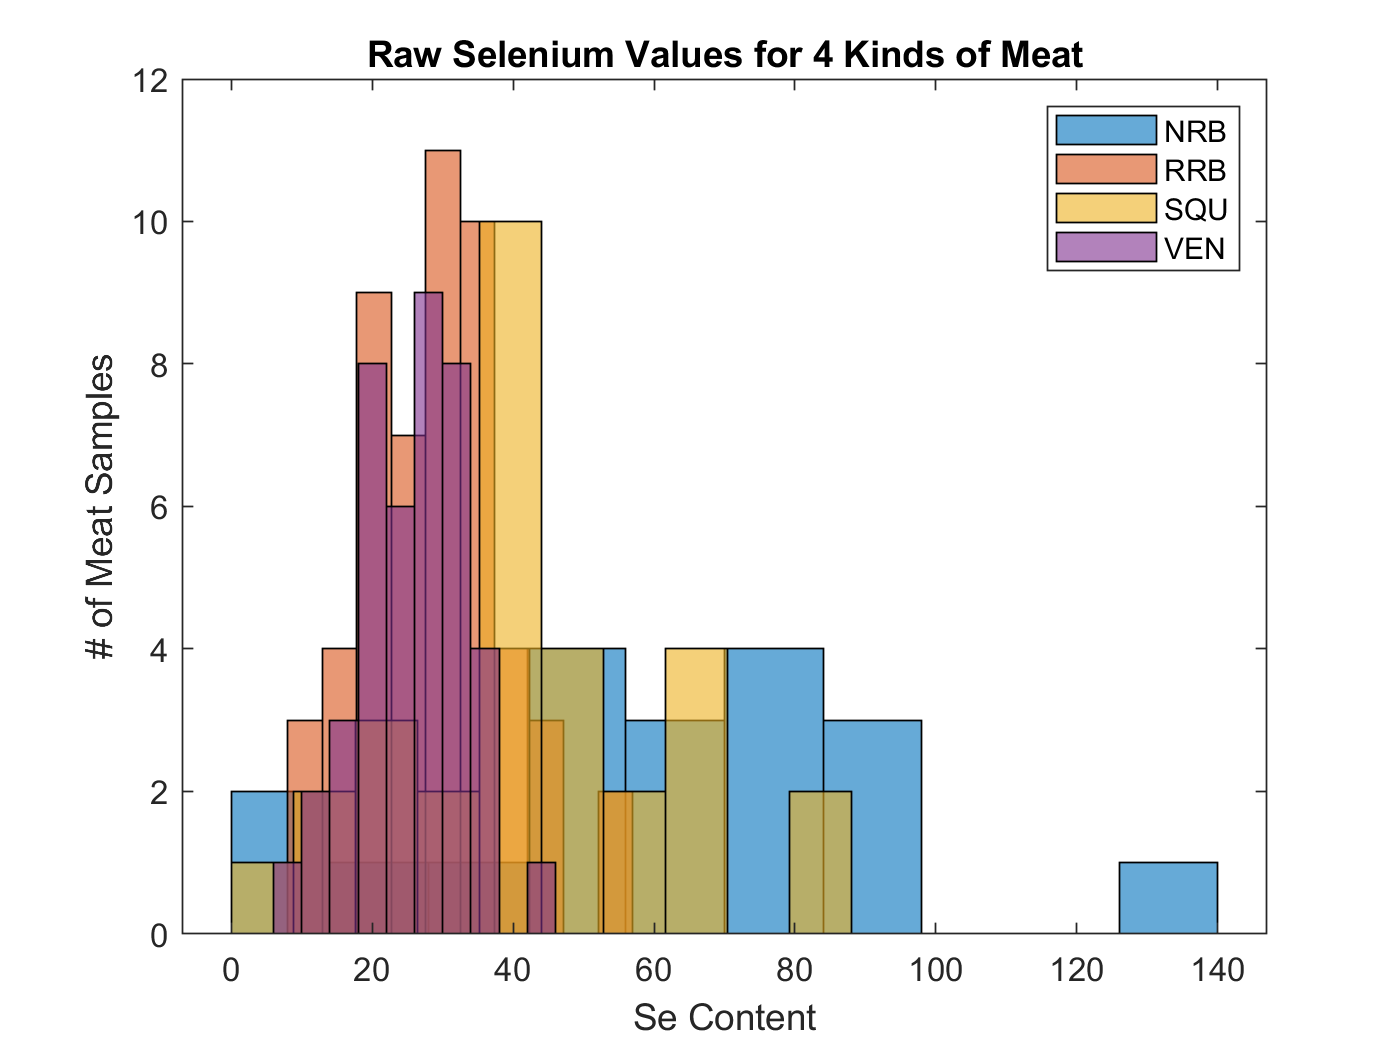

%Obtain the histogram plot of the dataset
figure
histogram(NRB,'NumBins',10)
hold on
histogram(RRB,'NumBins',10)
histogram(SQU,'NumBins',10)
histogram(VEN,'NumBins',10)
hold off

xlabel('Se Content')
ylabel('# of Meat Samples')
legend('NRB','RRB','SQU','VEN')
title('Raw Selenium Values for 4 Kinds of Meat')

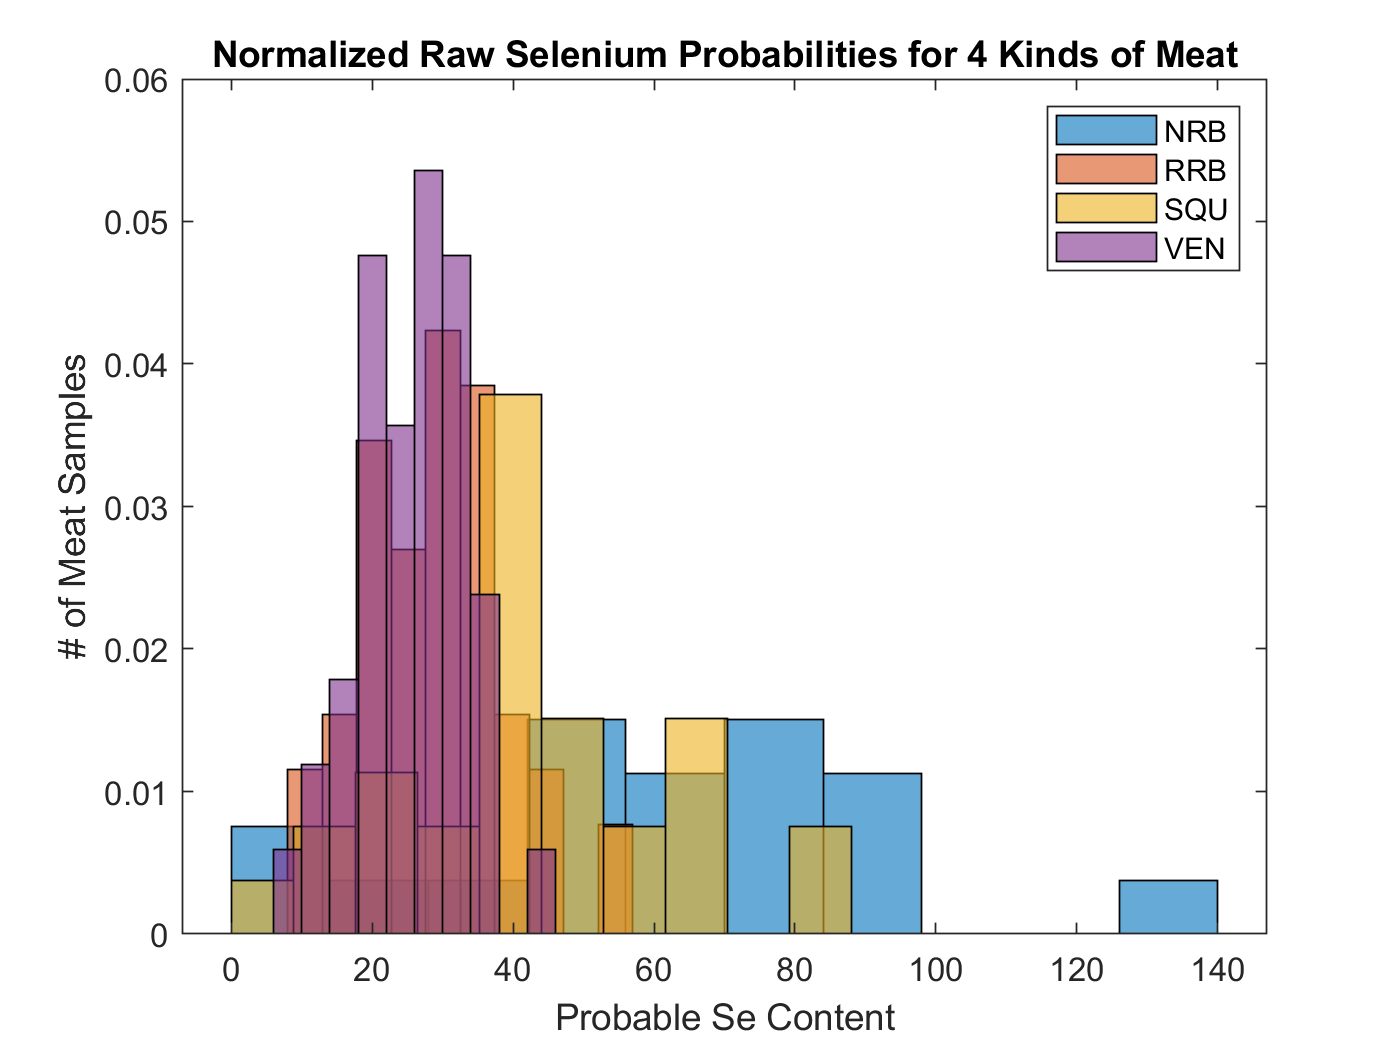

figure
%Obtain the histogram plot of the dataset
figure
histogram(NRB,'NumBins',10,'Normalization','pdf')
hold on
histogram(RRB,'NumBins',10,'Normalization','pdf')
histogram(SQU,'NumBins',10,'Normalization','pdf')
histogram(VEN,'NumBins',10,'Normalization','pdf')
hold off

xlabel('Probable Se Content')
ylabel('# of Meat Samples')
legend('NRB','RRB','SQU','VEN')
title('Normalized Raw Selenium Probabilities for 4 Kinds of Meat')

### Probability Density Functions

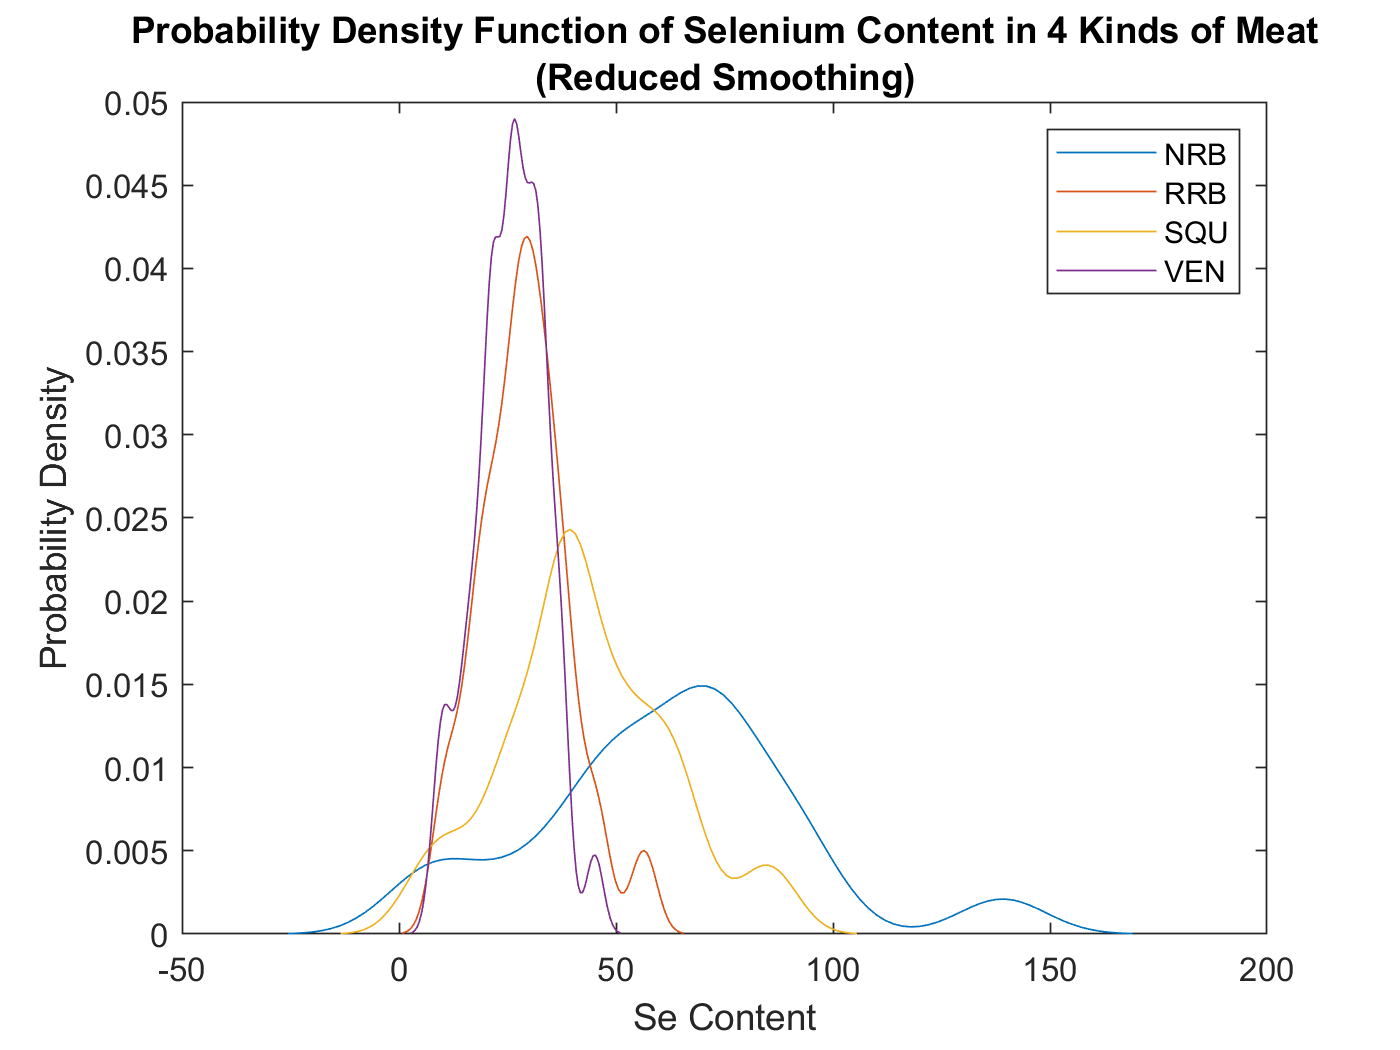

%'Bandwidth' adjusts how much filtering is applied: larger # = more
%filtering
figure
ksdensity(NRB,'Bandwidth',10) % Default Bandwidth = 15.6953
hold on
ksdensity(RRB,'Bandwidth',3) % Default Bandwidth = 4.6706
ksdensity(SQU,'Bandwidth',6) % Default Bandwidth = 9.5208
ksdensity(VEN,'Bandwidth',2) % Default Bandwidth = 3.7814
hold off


xlabel('Se Content')
ylabel('Probability Density')
legend('NRB','RRB','SQU','VEN')
title("Probability Density Function of Selenium Content in 4 Kinds of Meat"+newline+"(Reduced Smoothing)")

#### Take Aways

From the histograms/pdfs, it looks like with regards to Selenium content, Venison and Regional Raised Beef have similar concentrations and variance, while the Non-Regional Raised Beef and the Squirrel Meat follow this same pattern. However the latter seem to have larger means and variances.

### Boxplots

Boxplots are a great way to compare median, IQR (1st to 3rd), and outliers.  In Matlab, the whiskers extend to the farthest data points that are not considered outliers.  The default setting for Matlab is that an outliers is any value more extreme than 1.5*(Q3-Q1) away from the Q1 or Q3 value.

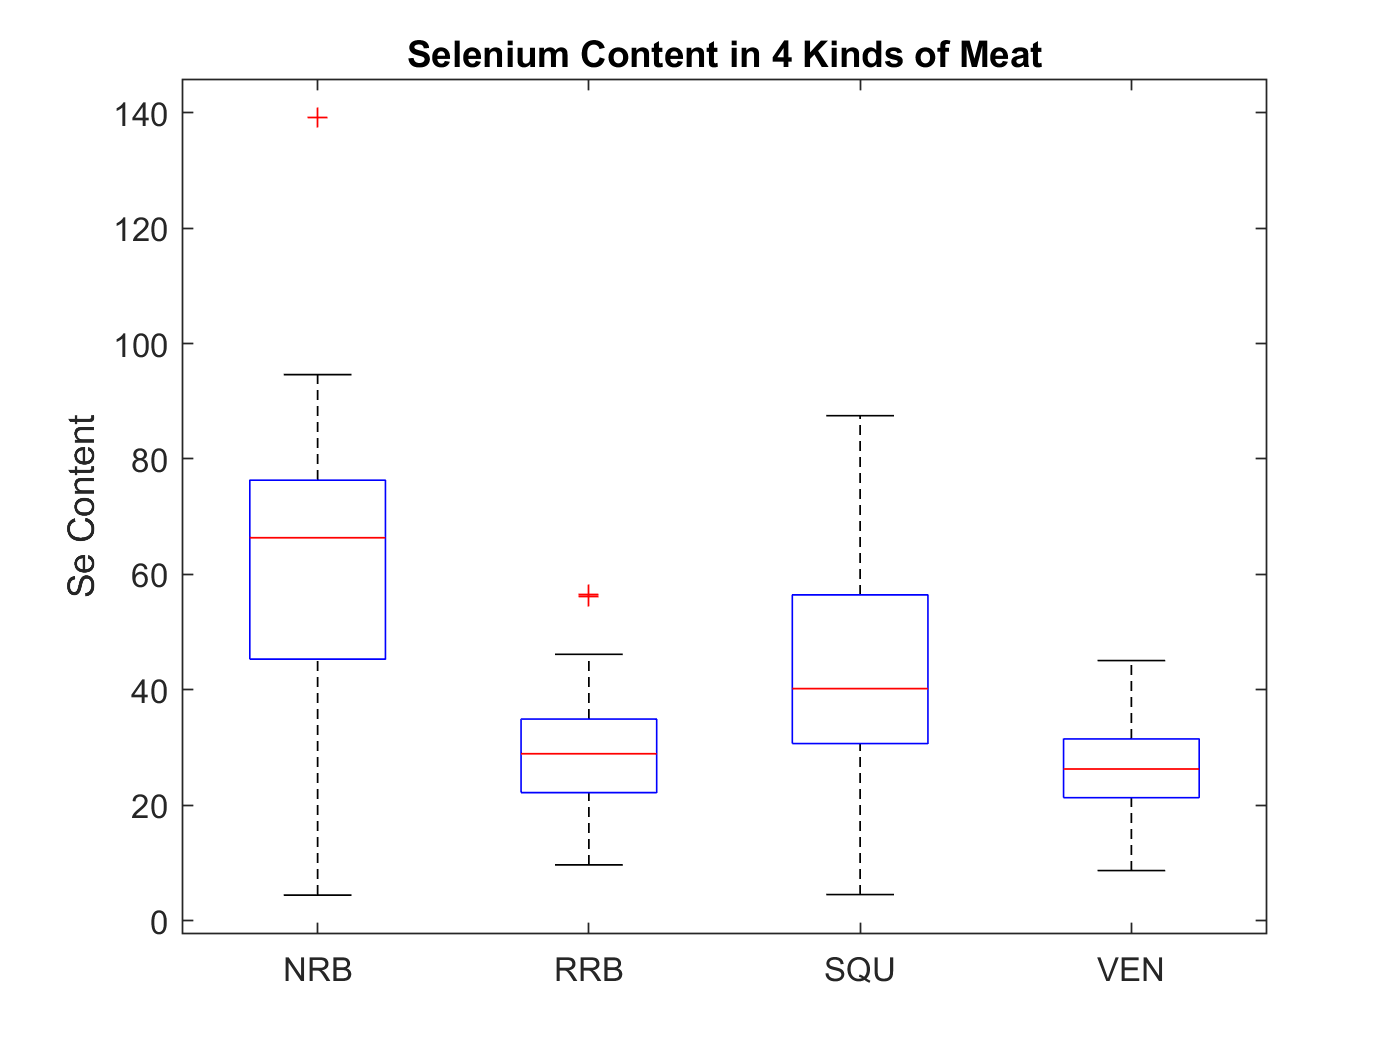

figure
boxplot(data,zdata,"Labels",{'NRB','RRB','SQU','VEN'})
ylabel ('Se Content')
title('Selenium Content in 4 Kinds of Meat')
hold off

#### Take Aways

These box plots also suggest that with regards to Selenium content, Venison and Regional Raised Beef have similar concentrations and variance, while the Non-Regional Raised Beef and the Squirrel Meat follow this same pattern. However the latter seem to have larger means and variances. It becoms more obvious, though, with this diagram, that the Non-Regional Raised Beef seems to have the highest mean Selenium concentration.

## DESCRIPTIVE STATISTICS - NUMERIC

## Univariate

%Set up a results table
tNRB = table();

tNRB.Mean = mean(NRB)';
tNRB.SD = std(NRB)';
tNRB.Med = median(NRB)';
tNRB.Max = max(NRB)';
tNRB.Min = min(NRB)';
tNRB.IQR = iqr(NRB)';

tRRB = table();

tRRB.Mean = mean(RRB)';
tRRB.SD = std(RRB)';
tRRB.Med = median(RRB)';
tRRB.Max = max(RRB)';
tRRB.Min = min(RRB)';
tRRB.IQR = iqr(RRB)';

tSQU = table();

tSQU.Mean = mean(SQU)';
tSQU.SD = std(SQU)';
tSQU.Med = median(SQU)';
tSQU.Max = max(SQU)';
tSQU.Min = min(SQU)';
tSQU.IQR = iqr(SQU)';

tVEN = table();

tVEN.Mean = mean(VEN)';
tVEN.SD = std(VEN)';
tVEN.Med = median(VEN)';
tVEN.Max = max(VEN)';
tVEN.Min = min(VEN)';
tVEN.IQR = iqr(VEN)';

ds = vertcat(tNRB,tRRB,tSQU,tVEN);
ds.Properties.RowNames = {'NRB','RRB','SQU','VEN'};
ds

ds = 4×6 table
            Mean       SD       Med       Max      Min      IQR 
           ______    ______    ______    ______    ____    _____

    NRB    62.046     31.15     66.36    139.09    4.45    30.99
    RRB    29.083    10.377     28.94     56.61    9.69    12.75
    SQU    43.246    19.509    40.225      87.5    4.55    25.75
    VEN    25.875    8.0324      26.3     45.08     8.7    10.17


#### Take Aways

The numeric, univariate statistics also suggest that with regards to average time spent on hold, Classical > Advertisement > Muzak. The other variables also generally follow this pattern.

### Bivariate

The most common bivariate statistic that we will utilize is the correlation coefficient.

This doesn't make sense to compute for this data/problem.

# INFERENTIAL STATISTICS

Our ultimate goal is to test the difference in means.  However, to do that, we need to first test the normality of the groups.  We also need to know if the groups have equal or unequal variance so that we know what t-test to use in our test of location.

## TEST OF NORMALITY

For a two-sample, independent test, we need to test the normality of each group.

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

Method: Anderson-Darling and Normality Plot

Step 1 : (Note that a non-directional test is assumed.)

H0 :$\gamma$_3 = 0 and $\gamma$_4 = 0 for all groups

H1 : $\gamma$_3 $\not=$ 0 and $\gamma$_4 $\not=$ 0 for some/all groups

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

alpha1 = 0.05

alpha1 = 0.0500

Step 3 : We will use the AD test statistic.

Step 4 : We will use the AD RSD

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    Quantitative: Reject H0 if any p-value < $\alpha$ 

Step 6 : Calculations

### Normality Plot & Anderson-Darling Statistic

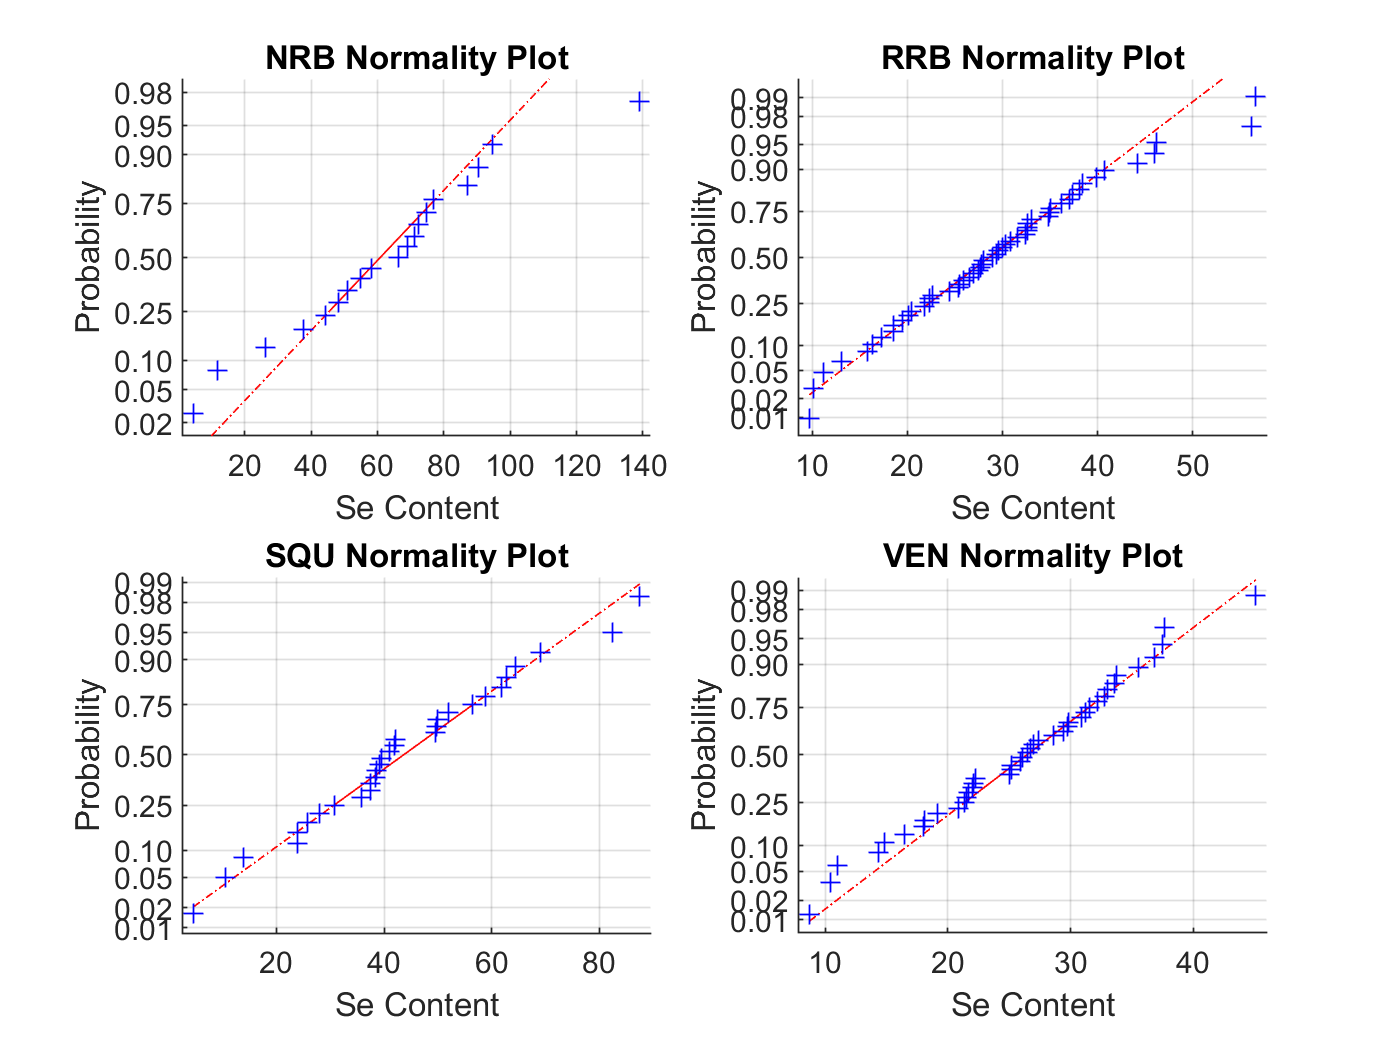

figure
subplot(2,2,1)
normplot(NRB) %quanlitative check
title('NRB Normality Plot')
xlabel('Se Content')

subplot(2,2,2)
normplot(RRB) %quanlitative check
title('RRB Normality Plot')
xlabel('Se Content')

subplot(2,2,3)
normplot(SQU) %quanlitative check
title('SQU Normality Plot')
xlabel('Se Content')

subplot(2,2,4)
normplot(VEN) %quanlitative check
title('VEN Normality Plot')
xlabel('Se Content')

**Take Aways**

This normality plot shows that all 4 populations roughly follow their respective linear regression lines, showing normality and a probable null hyopthesis for their respctive Anderson-Darling Tests.


%anderson-darling test for normality
% Ho: sample is normal, H1: sample is non-normal
[h1_norm(1),p1_norm(1), AD_stat(1), cv_norm(1)] = adtest(NRB);
[h1_norm(2),p1_norm(2), AD_stat(2), cv_norm(2)] = adtest(RRB);
[h1_norm(3),p1_norm(3), AD_stat(3), cv_norm(3)] = adtest(SQU);
[h1_norm(4),p1_norm(4), AD_stat(4), cv_norm(4)] = adtest(VEN);

h1_norm

h1_norm = 1×4 logical array
   0   0   0   0


p1_norm

p1_norm =     0.7214    0.7539    0.6894    0.9083


### Decision

Step 7a) Decision : **Fail to Reject H0** (for all 4 groups)

7b) p = see above

7c) We have sufficient statistical evidence to infer that the populations from which these data were randomly sampled are

symmetrical and mesokurtic, and, therefore, may be approximated by the Normal distribution. 

Based on n = (see below), the A-D tests are appropriate for this analysis.

n = [size(NRB,1) size(RRB,1) size(SQU,1) size(VEN,1)]

n =     19    53    30    42


Multiple sample size variables are appropriate for this problem because all groups have different sample sizes.

## TEST OF VARIANCE

The test of variance will tell us what t-test to use in the test of location.

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

- The data are normally distributed (all groups).

Method: For a three-sample, independent test:  Levene Test

Step 1 : (Note that a non-directional test is assumed.)

H0 : variance is equal for all groups

H1: variance is not equal across one or more groups

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

    We will use the same alpha as that for the normality test

alpha1

alpha1 = 0.0500

Step 3 : We will use the Levene's Test Statistic (F Statistic)

Step 4 : We will use the RSD for F with (n1-1, n2-1) degrees of freedom

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if p < 0.05

Step 6: Calculations

### Levene test for Variance

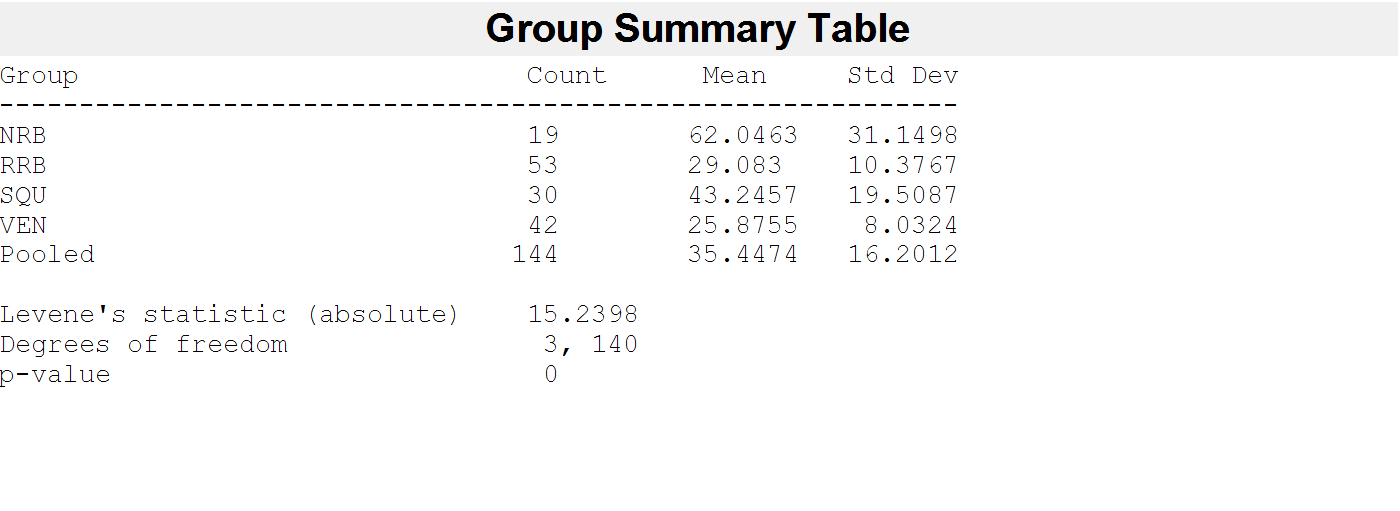

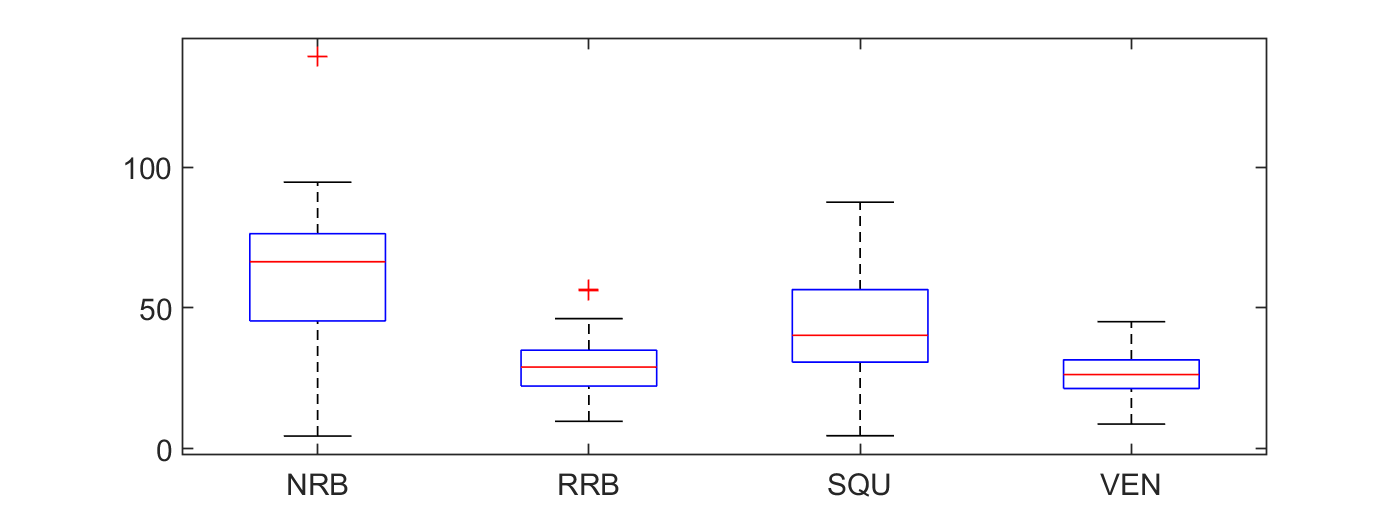

[p_var,STATS_var] = vartestn(raw.selenium,raw.type,'TestType','LeveneAbsolute');

Notice that the p-value is 0 .

### Decision

Step 7a) Decision : ** Reject H0**

7b) p = 0; Less than alpha

7c) We have sufficient statistical evidence to infer that one or more of the variances of the populations from which these samples were drawn are not equal**.**

## TEST OF LOCATION

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a randomly-drawn sample from a process/population (independent specimens).

- Independent, Unequal Variance may be known or assumed.

Method: Welch ANOVA

Step 1 : (Note that a non-directional test is assumed.)

H0 : All means are equal 

H1: All means are not equal (at least two means are statistically different)

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

    We will use the same alpha as that for the normality test

alpha1

alpha1 = 0.0500

Step 3 : We will use the F statistic.

Step 4 : We will use the RSD for F with 3 and 140 degrees of freedom.

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if p < alpha

Step 6: Calculations

[p_WANOVA,f_WANOVA,df1_WANOVA,df2_WANOVA] = wanova(data,zdata)

p_WANOVA = 9.6034e-05

f_WANOVA = 10.7539

df1_WANOVA = 2

df2_WANOVA = 62.9488

The p-value is less than alpha. 

### Decision

Step 7a) Decision : **Reject H0**

7b) p < .001 (p less than alpha)

7c) We have sufficient statistical evidence to infer that the means of one or more of the populations from which these samples were drawn are unequal. (If equal: The difference between mu_1 and mu_2 is due to sampling error, and sampling error alone.)

7d) Appropriate Point Estimates (Selenium Concentrations)

    *M_NRB = 62.05  |  M_RRB = 29.08  |  M_SQU = 43.25* *|  M_VEN = 25.88*

7e) Appropriate Interval Estimate(s)

%CI_NRB = paramci(extremes_NRB)
%CI_RRB = paramci(extremes_RRB)
%CI_SQU = paramci(extremes_SQU)
%CI_VEN = paramci(extremes_VEN)

7f) Effect Size

FOR ANOVA: We will need to find which groups are different, if we reject the null.  We do that through post-hoc analysis.

## Post-Hoc Analysis

Games-Howell b/c unequal variances (takes into account that they are unbalanced)

[h_GH,p_GH,stats_GH]=games_howell(data,zdata,alpha1)

h_GH =    NaN     1     0     1
     1   NaN     1     0
     0     1   NaN     1
     1     0     1   NaN


p_GH =        NaN    0.0027    0.1117    0.0020
    0.0027       NaN    0.0046    0.3308
    0.1117    0.0046       NaN    0.0014
    0.0020    0.3308    0.0014       NaN


stats_GH = struct with fields:
    gnames: [4×1 double]
        md: [4×4 double]
         q: [4×4 double]
        df: [4×4 double]


stats_GH.md

ans =        NaN   32.9633   18.8006   36.1708
  -32.9633       NaN  -14.1626    3.2075
  -18.8006   14.1626       NaN   17.3702
  -36.1708   -3.2075  -17.3702       NaN


stats_GH.q

ans =        NaN    6.3973    3.3299    7.0528
   -6.3973       NaN   -5.2208    2.4015
   -3.3299    5.2208       NaN    6.5137
   -7.0528   -2.4015   -6.5137       NaN


stats_GH.df

ans =        NaN   19.4500   27.0189   19.0916
   19.4500       NaN   38.4816   92.9600
   27.0189   38.4816       NaN   36.0743
   19.0916   92.9600   36.0743       NaN


**Take Aways:**

From the Games-Howell Test, we learn that the pairs of meat that do not reject H0 that there is no statistical difference in the populaiton means are [NRB, SQU] and [RRB,VEN]. The rest of the meats have statistically different means of Selenium content: [NRB > RRB], [NRB > VEN],  [SQU > RRB] and [SQU > VEN]. 

### Effect Size

[STATS_MES, varargout_mes] = mes1way(data,{'eta2','partialeta2','omega2','partialomega2'},'group',zdata);

summaryTable = 4×18 cell array
    {'source'        }    {'SS'        }    {'df' }    {'MS'        }    {'F'       }    {'p'         }    {'eta2'    }    {'ci_lo'   }    {'ci_up'   }    {'partialeta2'}    {'ci_lo'   }    {'ci_up'   }    {'omega2'  }    {'ci_lo'   }    {'ci_up'   }    {'partialomega2'}    {'ci_lo'   }    {'ci_up'   }
    {'between-groups'}    {[2.1262e+04]}    {[  3]}    {[7.0873e+03]}    {[ 27.0012]}    {[7.6827e-14]}    {[  0.3665]}    {[  0.2338]}    {[  0.4618]}    {[     0.3665]}    {[  0.2338]}    {[  0.4618]}    {[  0.3514]}    {[  0.2162]}    {[  0.4485]}    {[       0.3514]}    {[  0.2162]}    {[  0.4485]}
    {'within-groups' }    {[3.6747e+04]}    {[140]}    {[  262.4802]}    {0×0 double}    {0×0 double  }    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double   }    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double     }    {0×0 double}    {0×0 double}
    {'total'         }    {[5.8009e+04]}    {[143]}    {[

## CONCLUSION

Ultimately, we learned quite a few different things about our samples. First, from the Anderson-Darling Test we learned that all 4 populations can be assumed to be normally distributed. Second, we learned from the Levene test, that one or more of the variances of the groups was statistically different from the rest. Third, we learned from the Welche's ANOVA that one or more of our populations have a mean that is statistically different. Fourth, we learned from our Games-Howell Test in our Post-Hoc Analysis there is no statistical difference of the means for the following pairs of meat types: [NRB, SQU] and [RRB,VEN]. The rest of the meats have statistically different means of Selenium content: [NRB > RRB], [NRB > VEN],  [SQU > RRB] and [SQU > VEN]. Finally, we learned from our omega squared values that 35% of the overall variance comes from the difference in the means between the groups.